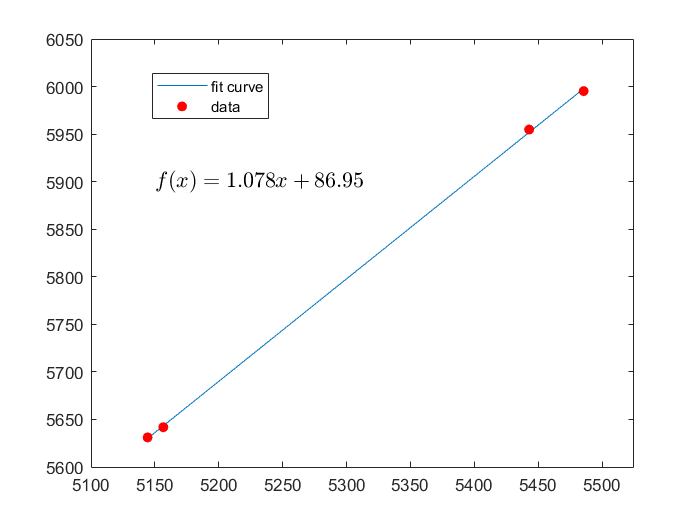

clear
M1 = readmatrix("刻度信息表20221110_195027.csv");
M2 = readmatrix("寻峰2.xlsx");
peak = M2(:,4);
N = 1:length(peak);
En = sort(M1(2:5,2));
adre = sort(M1(2:5,1));
ff = fit(En,adre,'poly1');
hold on
plot(En,ff(En))
scatter(En,adre,'red','filled')
box on

legend('fit curve','data')
legend("Position",[0.21702,0.77341,0.16679,0.086905])
text(5150,5900,'$f(x) = 1.078x+86.95$','Interpreter','latex','FontSize',13)
xlim([5100 5525])
ylim([5600 6050])

% hold on
% scatter(N,peak,'black','filled')
% xl=0:7;
% set(gca,'xtickLabel',xl);  %设置x轴显示的刻度（和数据无关）
% ff = fit(N',peak,'poly1')
% plot(ff)
% xlabel('N')
% ylabel('E')
% text(6,5300,'$\frac{dE}{dx}=382.8$','Interpreter','latex','FontSize',15)
% text(6,5000,'$\Delta X=$','Interpreter','latex','FontSize',15)
% grid on